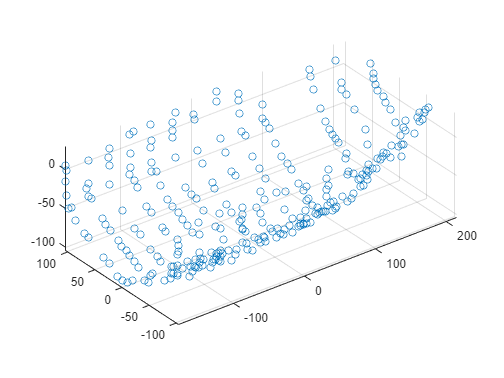

clc
clear
clf

Coord=load("point.m");%导入坐标点数据
x_axis=Coord(:,1);%x,y,z轴
y_axis=Coord(:,2);
z_axis=Coord(:,3);

%绘制散点图
figure,scatter3(x_axis,y_axis,z_axis)
axis equal%坐标轴比例


%绘制拟合曲面
figure
p =z_axis>100;
z_axis(p)=NaN;
[X,Y,Z]=griddata(x_axis,y_axis,z_axis,linspace(min(x_axis),max(x_axis))',linspace(min(y_axis),max(y_axis)),'v4');%插值

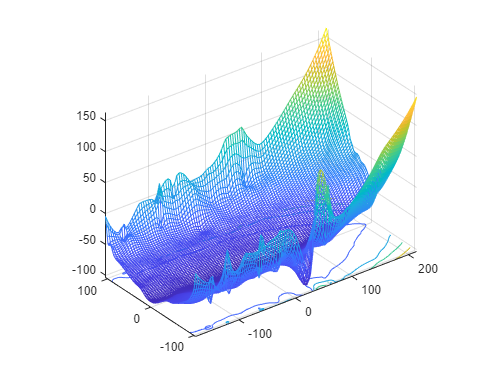

figure,meshc(X,Y,Z);%三维曲面+等高线
set(gca,'DataAspectRatio',[1 1 1])%设置坐标轴比例
hidden off



mesh.xs =x_axis;
mesh.ys =y_axis;
mesh.zs =z_axis;

[mesh.xgrid,mesh.ygrid,mesh.zgrid]=meshgrid(mesh.xs,mesh.ys,mesh.zs);

cube.density=1.716;

masses_3D = cube.density * ones(size(mesh.xgrid));
M_2Dplate = matrixsum(masses_3D);
COM3D=COMof3D(masses_3D,mesh)

COM3D =     4.4006   -3.9527  -43.8170


function M = matrixsum(masses)

M = sum(masses(:));

end

